close('all'); clear; clc;
setmadsympath();

## Geometry

The Sharp model considers a left-handed frame (North, West, Down).

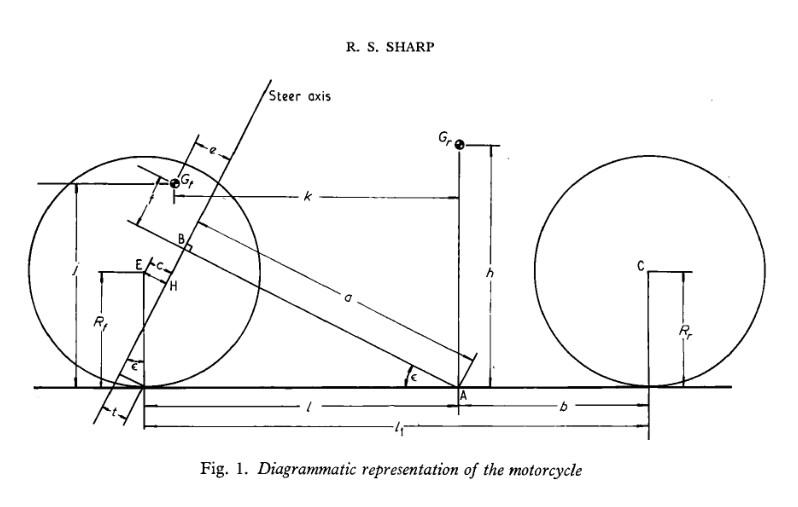

Create the caster frame:

caster = newParameters('varepsilon');
N = Frame;
Nc = N.orientNew('y',caster);

Solve for the front wheelbase $l$:

[a,an,l] = newParameters('a','a_n','l');
Pa = Point;
Pb = Pa.locateNew(a*Nc.x);
l = solve(cos(caster) == a/(l + an/cos(caster)),l)

$$l = \frac{a-a_{n}}{\cos\left(\varepsilon \right)}$$

Locate the front wheel center $E$:

rf = newParameters('r_f');
E = Pa.locateNew(l*N.x - rf*N.z);
rE = E.posFrom

$$rE = \left[\begin{array}{c} \frac{a-a_{n}}{\cos\left(\varepsilon \right)}\\ 0\\ -r_{f} \end{array}\right]$$

Now locate the front wheel center relative to the intersection between the front chassis chord and the steering axis:

rBE = simplify(expand(Ry(caster).'*E.posFrom(Pb)));
lx = rBE(1)

$$lx = r_{f}\,\sin\left(\varepsilon \right)-a_{n}$$

lz = rBE(3)

$$lz = -\frac{r_{f}\,{\cos\left(\varepsilon \right)}^{2}-a\,\sin\left(\varepsilon \right)+a_{n}\,\sin\left(\varepsilon \right)}{\cos\left(\varepsilon \right)}$$

Now solve for the front chassis chord $a$ and the height $f$ of the front chassis mass center in the caster frame to obtain a simplifying substitution for $l_{z}$:

[e,f,j,k] = newParameters('e','f','j','k');
Gfa = Pa.locateNew(k*N.x - j*N.z);
Gf = Pb.locateNew(e*Nc.x + f*Nc.z);
sol_af = solve(Gf.posFrom(Gfa) == 0,[a,f]);
lz_sub = simplify(expand(subs(lz,a,sol_af.a)))

$$lz\_sub = -\frac{j\,{\cos\left(\varepsilon \right)}^{2}-j+r_{f}\,{\cos\left(\varepsilon \right)}^{2}+a_{n}\,\sin\left(\varepsilon \right)+e\,\sin\left(\varepsilon \right)-k\,\cos\left(\varepsilon \right)\,\sin\left(\varepsilon \right)}{\cos\left(\varepsilon \right)}$$


clearvars -except a an l rf caster lx lz e f j k sol_af;

## Generalized coordinates

t = sym('t');

Translation of the motorcycle origin $A$:

[x,y] = dynamicVariables('x','y');

Orientation of the rear chassis frame:

[yaw,lean] = dynamicVariables('psi','varphi');

Orientation of the front wheel:

[yaw_f,lean_f] = dynamicVariables('psi_f','varphi_f');

Steering angle:

steer = dynamicVariables('delta');

Rotation angles of the rear and front wheels:

[pitch_r,pitch_f] = dynamicVariables('theta_r','theta_f');

Generalized coordinates:

q = [x,y,yaw,steer,lean,yaw_f,lean_f,pitch_f,pitch_r].';
qd = diff(q,t);
qdd = diff(qd,t);

### Quasi velocities

[vx,vy,uyaw,usteer,ulean] = ...
    dynamicVariables('v_x','v_y','u_psi','u_delta','u_varphi');
u = [vx,vy,uyaw,usteer,ulean].';
ud = diff(u,t);

### Lagrange multipliers

lm = dynamicVariables('lambda',1:4)

$$lm = \left[\begin{array}{c} \lambda_{1}\left(t\right)\\ \lambda_{2}\left(t\right)\\ \lambda_{3}\left(t\right)\\ \lambda_{4}\left(t\right) \end{array}\right]$$

lmd = diff(lm,t);

### Force inputs

Rear and front tire lateral forces:

[Yr,Yf] = dynamicVariables('Y_r','Y_f');
Y = [
    Yr;
    Yf
    ];
p = numel(Y);

Yrd = diff(Yr,t);
Yfd = diff(Yf,t);
Yd = [
    Yrd;
    Yfd
    ];

Steering torque:

Msteer = dynamicVariables('tau');

Input forces:

F = [Yr,Yf,Msteer].';
Fd = diff(F,t);

## Kinematics

### Rear chassis

Orientation:

N = Frame;
Nyaw = N.orientNew('z',yaw);
Nlean = Nyaw.orientNew('x',lean);
pprint(Nlean.dcm)

$$\left[\begin{array}{ccc} \cos\left(\psi \right) & -\cos\left(\phi \right)\,\sin\left(\psi \right) & \sin\left(\psi \right)\,\sin\left(\phi \right)\\ \sin\left(\psi \right) & \cos\left(\psi \right)\,\cos\left(\phi \right) & -\cos\left(\psi \right)\,\sin\left(\phi \right)\\ 0 & \sin\left(\phi \right) & \cos\left(\phi \right) \end{array}\right]$$

Position:

P0 = Point;
Pa = P0.locateNew(x.*N.x + y.*N.y);
h = newParameters('h');
Gr = Pa.locateNew(-h.*Nlean.z);
pprint(Gr.posFrom)

$$\left[\begin{array}{c} x-h\,\sin\left(\psi \right)\,\sin\left(\phi \right)\\ y+h\,\cos\left(\psi \right)\,\sin\left(\phi \right)\\ -h\,\cos\left(\phi \right) \end{array}\right]$$

### Rear wheel

Orientation:

Npitch_r = Nlean.orientNew('y',pitch_r);
pprint(Npitch_r.dcm);

$$\left[\begin{array}{ccc} \cos\left(\psi \right)\,\cos\left(\theta_{r}\right)-\sin\left(\psi \right)\,\sin\left(\theta_{r}\right)\,\sin\left(\phi \right) & -\cos\left(\phi \right)\,\sin\left(\psi \right) & \cos\left(\psi \right)\,\sin\left(\theta_{r}\right)+\cos\left(\theta_{r}\right)\,\sin\left(\psi \right)\,\sin\left(\phi \right)\\ \cos\left(\theta_{r}\right)\,\sin\left(\psi \right)+\cos\left(\psi \right)\,\sin\left(\theta_{r}\right)\,\sin\left(\phi \right) & \cos\left(\psi \right)\,\cos\left(\phi \right) & \sin\left(\psi \right)\,\sin\left(\theta_{r}\right)-\cos\left(\psi \right)\,\cos\left(\theta_{r}\right)\,\sin\left(\phi \right)\\ -\cos\left(\phi \right)\,\sin\left(\theta_{r}\right) & \sin\left(\phi \right) & \cos\left(\theta_{r}\right)\,\cos\left(\phi \right) \end{array}\right]$$

Position:

[b,rr] = newParameters('b','r_r');
Wr = Pa.locateNew(-b.*Nlean.x -rr.*Nlean.z);
pprint(Wr.posFrom)

$$\left[\begin{array}{c} x-b\,\cos\left(\psi \right)-r_{r}\,\sin\left(\psi \right)\,\sin\left(\phi \right)\\ y-b\,\sin\left(\psi \right)+r_{r}\,\cos\left(\psi \right)\,\sin\left(\phi \right)\\ -r_{r}\,\cos\left(\phi \right) \end{array}\right]$$

#### Rear contact point

Cr = Wr.locateNew(rr*Nlean.z);
rWrCr = simplify(expand(Cr.posFrom(Wr,Npitch_r)));
pprint(rWrCr)

$$\left[\begin{array}{c} -r_{r}\,\sin\left(\theta_{r}\right)\\ 0\\ r_{r}\,\cos\left(\theta_{r}\right) \end{array}\right]$$

### Front chassis

Orientation:

Ncaster = Nlean.orientNew('y',caster);
Nsteer = Ncaster.orientNew('z',steer);

Position:

Pb = Pa.locateNew(a.*Ncaster.x);
Gf = Pb.locateNew(e.*Nsteer.x + f.*Nsteer.z);

### Front wheel

Orientation:

Nyaw_f = N.orientNew('z',yaw_f);
Nlean_f = Nyaw_f.orientNew('x',lean_f);
Npitch_f = Nlean_f.orientNew('y',pitch_f);

Position:

Wf = Pb.locateNew(lx.*Nsteer.x + lz.*Nsteer.z);

#### Front contact point

Cf = Wf.locateNew(rf.*Nlean_f.z);
rWfCf = simplify(expand(Cf.posFrom(Wf,Npitch_f)));
pprint(rWfCf)

$$\left[\begin{array}{c} -r_{f}\,\sin\left(\theta_{f}\right)\\ 0\\ r_{f}\,\cos\left(\theta_{f}\right) \end{array}\right]$$

## Constraints

### Holonomic constraints

spin_x = simplify(expand(Nsteer.y(1) - Nlean_f.y(1)));
spin_z = simplify(expand(Nsteer.y(3) - Nlean_f.y(3)));

hc = [
    spin_z;
    spin_x
    ];

pprint(hc)

$$\left[\begin{array}{c} \cos\left(\delta \right)\,\sin\left(\phi \right)-\sin\left(\phi_{f}\right)+\sin\left(\delta \right)\,\cos\left(\phi \right)\,\sin\left(\varepsilon \right)\\ \cos\left(\phi_{f}\right)\,\sin\left(\psi_{f}\right)-\cos\left(\delta \right)\,\cos\left(\phi \right)\,\sin\left(\psi \right)-\cos\left(\psi \right)\,\sin\left(\delta \right)\,\cos\left(\varepsilon \right)+\sin\left(\delta \right)\,\sin\left(\psi \right)\,\sin\left(\phi \right)\,\sin\left(\varepsilon \right) \end{array}\right]$$

### Nonholonomic constraints

eulvel = @(N,P,r)[-N.dcm*vec2skew(r),N.dcm]*Twist(Pose(N,P)).Vector;

slip_r = Nyaw.dcm.'*eulvel(Npitch_r,Wr,rWrCr);
no_slip_r = simplify(expand(N.x.'*slip_r));
pprint(no_slip_r)

$$r_{r}\,{\dot{\theta }}_{r}+\dot{x}\,\cos\left(\psi \right)+\dot{y}\,\sin\left(\psi \right)$$


slip_f = Nyaw_f.dcm.'*eulvel(Npitch_f,Wf,rWfCf);
no_slip_f = simplify(expand(N.x.'*slip_f));

nhc = [
    no_slip_r;
    no_slip_f
    ];

### Constraint matrix

constraints = [
    diff(hc,t);
    nhc
    ];

A = simplify(expand(jacobian(constraints,qd)));

## Rigid bodies

B = @(N,P,m,I)struct( ...
    "N",N, ...
    "P",P, ...
    "V",Twist(Pose(N,P)).Vector, ...
    "J",Twist(Pose(N,P)).jacobian(qd), ...
    "Vd",diff(Twist(Pose(N,P)).Vector,t), ...
    "Jd",diff(Twist(Pose(N,P)).jacobian(qd),t), ...
    "m",m, ...
    "I",I, ...
    "G",blkdiag(I,m.*eye(3)) ...
    );

### Rear chassis

mr = newParameters('m_r');
[Irx,Iry,Irz,Crxz] = newParameters('I_rx','I_ry','I_rz','C_rxz');
Ir = inertia(Irx,Iry,Irz,'Ixz',Crxz);
rear_chassis = B(Nlean,Gr,mr,Ir);

### Rear wheel

iry = sym('i_ry');
Irw = inertia(0,iry,0);
rear_wheel = B(Npitch_r,Wr,0,Irw);

### Front chassis

[mf,Ifx,Ifz] = newParameters('m_f','I_fx','I_fz');
If = inertia(Ifx,0,Ifz);
front_chassis = B(Nsteer,Gf,mf,If);

### Front wheel

ify = sym('i_fy');
Ifw = inertia(0,ify,0);
front_wheel = B(Npitch_f,Wf,0,Ifw);

bodies = [
    rear_chassis;
    rear_wheel;
    front_chassis;
    front_wheel
    ];

## Lagrangian

fL = @(b)(1/2).*b.V.'*b.G*b.V;
L = simplify(expand(sum(arrayfun(fL,bodies))));

## Inertial forces

Qi = diff(jacobian(L,qd).',t) - jacobian(L,q).' - A.'*lm;

## Active forces

wrench = @(N,P,w)Pose(N,P).inv().Adjoint.'*w;
force = @(N,P,f)wrench(N,P,[zeros(3,1);f]);
moment = @(N,P,m)wrench(N,P,[m;zeros(3,1)]);
J = @(b)Pose(b.N,b.P).Adjoint*b.J;

### Rear tire forces

Zr = sym('Z_r');
Wrw = force(Nyaw,Cr,[0;Yr;Zr]);
Qr = simplify(expand(J(rear_wheel).'*Wrw));
pprint(Qr)

$$\left[\begin{array}{c} -Y_{r}\,\sin\left(\psi \right)\\ Y_{r}\,\cos\left(\psi \right)\\ -Y_{r}\,b\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0 \end{array}\right]$$

### Front tire forces

Zf = sym('Z_f');
Wfw = force(Nyaw_f,Cf,[0;Yf;Zf]);
Qf = simplify(expand(J(front_wheel).'*Wfw));

### Steering torque

Csteer = sym('C_delta');
Wsteer = moment(Nsteer,Gf,[0;0;Msteer - Csteer*qd(4)]);
Qsteer = (J(front_chassis) - J(rear_chassis)).'*Wsteer;
Qsteer = simplify(expand(Qsteer));
pprint(Qsteer)

$$\left[\begin{array}{c} 0\\ 0\\ 0\\ \tau -C_{\delta }\,\dot{\delta }\\ 0\\ 0\\ 0\\ 0\\ 0 \end{array}\right]$$

### Gravity

g = sym('g');
fg = @(b)J(b).'*force(N,b.P,[0;0;b.m*g]);
Qg = sum(cell2sym(arrayfun(fg,bodies.','uniform',0)),2);
Qg = simplify(expand(Qg));

### Generalized forces

Qa = simplify(expand(Qr + Qf + Qsteer + Qg));

## Tire equations

vCr = simplify(expand(Twist(Pose(Nyaw,Cr)).TranslationalVelocity));
vCf = simplify(expand(Twist(Pose(Nyaw_f,Cf)).TranslationalVelocity));

rl = newParameters('sigma');
[Cr1,Cr2,Cf1,Cf2] = newParameters('C_r1','C_r2','C_f1','C_f2');

eqYr = (rl./vCr(1)).*Yrd + ...
    Yr + Cr1*atan(vCr(2)/vCr(1)) - ...
    Cr2*lean;

eqYf = (rl./vCf(1)).*Yfd + ...
    Yf + Cf1*atan(vCf(2)/vCf(1)) - ...
    Cf2*lean_f;

eqY = [
    eqYr;
    eqYf
    ];

## Equations of motion

eom = [
    Qi - Qa;
    diff(A*qd,t)
    ];

### Mass matrix

mass_matrix = simplify(expand(jacobian(eom,[qdd;lm])));

### Forcing vector

forcing_vector = -subs(eom,[qdd;lm],0.*[qdd;lm]);

## Straight running conditions

% v = sym('V');
% 
% q0 = 0.*q;
% q0(has(q,x)) = v*t;
% q0(has(q,pitch_r)) = -v*t/rr;
% q0(has(q,pitch_f)) = -v*t/rf;
% 
% qd0 = diff(q0,t);
% qdd0 = diff(qd0,t);
% q0 = 0.*q0;
% 
% Y0 = 0.*Y;
% Yd0 = 0.*Yd;
% 
% Msteer0 = 0.*Msteer;
% 
% vars = [
%     qdd;
%     qd;
%     q;
%     Yd;
%     Y;
%     Msteer
%     ];
% 
% trim_vals = [
%     qdd0;
%     qd0;
%     q0;
%     Yd0;
%     Y0;
%     Msteer0
%     ];

### Solve Lagrange multipliers

% M0 = simplify(expand(subs(mass_matrix,vars,trim_vals)));
% f0 = simplify(expand(subs(forcing_vector,vars,trim_vals)));
% lm_sol = simplify(expand(syminv(M0)*f0));
% disp(lm_sol.')
% vars = [vars;lmd;lm];
% trim_vals = [trim_vals;lm_sol(end-3:end);lm_sol(end-3:end)];

## Linearization

### Equations of motion

% flin = @(f,q,q0)subs(f,q,q0) + subs(jacobian(f,q),q,q0)*(q - q0);
% feq_lin = @(f)flin(f,vars,trim_vals);
% eom_lin = cell2sym(arrayfun(feq_lin,eom,'uniform',0));
% eom_lin = simplify(expand(eom_lin));

### Constraint equations

% eqc_lin = int(int(eom_lin(end-3:end),t),t);
% pprint(eqc_lin)

### Tire equations

% eqY_lin = cell2sym(arrayfun(feq_lin,eqY,'uniform',0));
% eqY_lin = simplify(expand(eqY_lin));

## Independent coordinate formulation

% qdep = [
%     yaw_f;
%     lean_f;
%     pitch_r;
%     pitch_f
%     ];
% 
% qind = q(~has(q,qdep));
% qdind = diff(qind,t);

### Dependent coordinate solution

% [Aqdep,bqdep] = equationsToMatrix(eqc_lin,qdep);
% qdep_sol = Aqdep\bqdep;
% pprint(qdep_sol)

### Velocity projection matrix

% R = jacobian([qind;qdep_sol],qind);
% pprint(R)

### Equations of motion

% eom_ind = R.'*subs(eom_lin(1:end-4),qdep,qdep_sol);
% eom_ind = simplify(expand(eom_ind));

### Tire equations

% eqY_ind = simplify(expand(subs(eqY_lin,qdep,qdep_sol)));

## Sharp's equations

### Geometric simplifications

% eom_sharp = subs(eom_ind,[a;f],[sol_af.a;sol_af.f]);
% eom_sharp = simplify(expand(eom_sharp));
% 
% eqY_sharp = subs(eqY_ind,[a;f],[sol_af.a;sol_af.f]);
% eqY_sharp = simplify(expand(eqY_sharp));

### Kinematic equations

% va = simplify(expand(Twist(Pose(Nyaw,Pa)).TranslationalVelocity));
% 
% kdes = [
%     u(1:2) - va(1:2);
%     u(3:5) - qd(3:5)
%     ];
% 
% Jqd = jacobian(u - kdes,diff(qind,t));
% Ju = simplify(expand(inv(Jqd)));
% 
% u0 = [v;zeros(4,1)];
% feqv_lin = @(f)flin(f,[qdind;u;yaw],[u0;u0;0]);
% kdes_lin = cell2sym(arrayfun(feqv_lin,Ju*u,'uniform',0));
% kdes_lin = simplify(expand(kdes_lin));
% pprint(kdes_lin)

### First order reduction

% eqs_sharp = [
%     subs(subs(eom_sharp(2:end),qdind,kdes_lin),qdind,kdes_lin);
%     subs(eqY_sharp,qdind,kdes_lin);
%     qd(4:5) - u(4:5);
%     ];
% eqs_sharp = simplify(expand(eqs_sharp));

## State space equations

### State vector

% X = [u(2),steer,lean,Yr,Yf,u(3:5).'].';
% Xd = diff(X,t);

### Mass matrix

% dM = simplify(expand(jacobian(eqs_sharp,Xd)));
% pprint(dM)

### Forcing vector

% df = simplify(expand(-subs(eqs_sharp,Xd,0.*Xd)));

### Forcing matrix

% dF = jacobian(df,X);
% oval = j*sin(caster);
% nval = a - cos(caster)*k + e;
% dF = simplify(expand(subs(dF,oval,nval)));
% pprint(dF)

### Input matrix

% dG = jacobian(df,Msteer);
% pprint(dG)

### State space matrices

% Minv = syminv(dM);
% A = Minv*dF;
% B = Minv*dG;

## Linear analysis

% params = symvar(A).';
% params(params == v) = [];
% params_sub = sharpMotorcycle1971Parameters().list;
% fA = matlabFunction(subs(A,params,params_sub),'Vars',v);
% fB = matlabFunction(subs(B,params,params_sub),'Vars',v);
% 
% StateName = [
%     "v_y";
%     "steer";
%     "lean";
%     "Y_r";
%     "Y_f";
%     "yaw rate";
%     "steer rate";
%     "lean rate"
%     ];
% 
% StateUnit = [
%     "m/s";
%     "rad";
%     "rad";
%     "N";
%     "N";
%     "rad/s";
%     "rad/s";
%     "rad/s"
%     ];
% 
% InputName = "steering torque";
% InputUnit = "Nm";
% 
% fsys = @(v)ss(fA(v),fB(v),eye(size(fA(v))),0, ...
%     "StateName",StateName, ...
%     "StateUnit",StateUnit, ...
%     "InputName",InputName, ...
%     "InputUnit",InputUnit, ...
%     "OutputName",StateName, ...
%     "OutputUnit",StateUnit ...
%     );

### Nyquist plot

% vx = (1/3.6).*linspace(1,220,500).';
% poles_lagrange = cell2mat(arrayfun(@(vx)eig(fA(vx)).',vx,'uniform',0));
% save("poles_lagrange.mat","poles_lagrange",'-mat');
% y = poles_lagrange;
% fig = figure();
% axe = axes(fig);
% hold on
% Cdata = matplotlibcolors;
% Cdata = Cdata(1:numel(X),:);
% frl = @(x,c)scatter(real(x),imag(x),5,'filled','CData',c);
% cellfun(frl,num2cell(y,1),num2cell(Cdata,2).');
% hold off
% box on
% grid on
% xlim([-115,5]);
% ylim([-60,60]);
% xlabel('Re');
% ylabel('Im');